## SimpleSharpRange.mlx

is an example of rading an analog Sharp IR Range sensor on an Arduino

hook analog out from sesnor into Pin A0, Vcc to 5 VDC, and gnd to gnd.

Program collects range voltrage data, plots it, and is terminated by operator input.

Dowling Feb28, revision1

clc                                     % clear command window
clear                                   % clear MATLAB workspace

## Set up robot control system (code that runs once)

[robotArduino, rawRangeIn1, rawRangeIn2, rawRangeIn3, rawRangeIn4, rawRangeIn5, blinkLED] = SETUPARDUINO('/dev/cu.usbmodem14101', 'Uno');
Blink(robotArduino, blinkLED, 5);
disp('Parking sonar activated');

Parking sonar activated


disp('Working scale: 5-40cm');

Working scale: 5-40cm


## Run Robot Control Loop (code that runs over and over)

rangeData = 0

rangeData = 1.5054

rangeData = 0.4643

rangeData = 0.4643

rangeData = 0.2737

IRData =    93.6082   55.0311   55.0311   16.7237       Inf


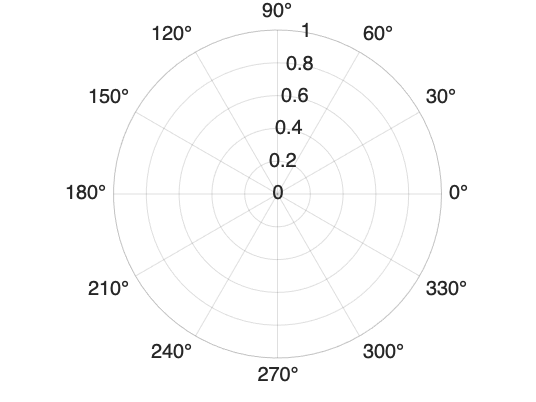

Error using polarhistogram
Incorrect number of input arguments. Each parameter name must be followed by a corresponding value.

 controlFlag = 1;                         % create a loop control
 while (controlFlag<2)
     positionData = zeros(1,5);
     distanceData = zeros(1,5);
     rangeData= SENSE(robotArduino, rawRangeIn1)
     positionData(controlFlag, 1)=rangeData;
     distanceData(1,1)=(25.72/rangeData)-0.3617;
     pause(0.1);
 
     rangeData= SENSE(robotArduino, rawRangeIn2)
     positionData(controlFlag, 2)=rangeData;
     distanceData(1,2)=(25.72/rangeData)-0.3617;
     pause(0.1);
 
     rangeData= SENSE(robotArduino, rawRangeIn3)
     positionData(controlFlag, 3)=rangeData;
     distanceData(1,3)=(25.72/rangeData)-0.3617;
     pause(0.1);
 
     rangeData= SENSE(robotArduino, rawRangeIn4)
     positionData(controlFlag, 4)=rangeData;
     distanceData(1,4)=(25.72/rangeData)-0.3617;
     pause(0.1);

     rangeData= SENSE(robotArduino, rawRangeIn5)
     positionData(controlFlag, 5)=rangeData;
     distanceData(1,5)=(25.72/rangeData)-0.3617;
     pause(0.1);
     IRData=[distanceData(1,5) distanceData(1,4) distanceData(1,3) distanceData(1,2) distanceData(1,1)]
     polarhistogram('BinEdges',[0 pi/5 2*pi/5 3*pi/5 4*pi/5 pi],'BinCounts', 4, IRData)
 
 
     
 end

## Clean and shutdown

 clc
 disp('Arduino program has ended');
 clear robotArduino
 beep

## Robot Functions (store this codes local functions here)

In practice for modularity, readability and longiteveity, your main robot code should be as brief

as possible and the bulk of the work should be done by functions

function [robotArduino, rawRangeIn1, rawRangeIn2, rawRangeIn3, rawRangeIn4, rawRangeIn5, blinkLED] = SETUPARDUINO(COMPORT, MODEL)
% Create a global arduino object so that it can be used in functions
robotArduino = arduino(COMPORT, MODEL, 'Libraries', 'Servo');
 
% configure pin 13 as a digitial-out LED
 blinkLED = 'D13';
 configurePin(robotArduino, blinkLED, 'DigitalOutput');
 
 % configure A0 pin as an analog input
 rawRangeIn1 = 'A0';
 configurePin(robotArduino, rawRangeIn1, 'AnalogInput');
 
 rawRangeIn2 = 'A1';
 configurePin(robotArduino, rawRangeIn2, 'AnalogInput');
 
 rawRangeIn3 = 'A2';
 configurePin(robotArduino, rawRangeIn3, 'AnalogInput');
 
 rawRangeIn4 = 'A3';
 configurePin(robotArduino, rawRangeIn4, 'AnalogInput');
 
 rawRangeIn5 = 'A4';
 configurePin(robotArduino, rawRangeIn5, 'AnalogInput');
 
end
 
 function [] = Blink(a,LED, n)
     for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
     end
 end

## **Sense Functions (store all Snese related local functions here)**

 function rangeData=SENSE(robotArduino, rawRangeIn)
     rangeData = readVoltage(robotArduino, rawRangeIn);
 end

## Think Function (store all Think related local functions here)

 function THINK(time)
     %null
 end

## Act Functions (store all Act related local functions here)

 function ACT(time)
     %null
 end
